# Writing an ODE Function, part 1

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves the ODE system and visualizes the solution.

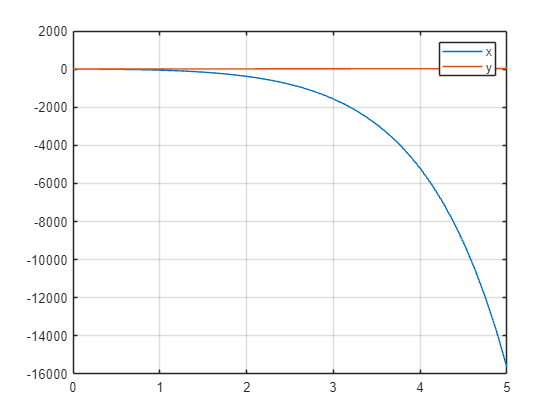

tRange = [0 5];
Y0 = [1; 3];
[tSol, YSol] = ode45(@myODEfun1, tRange, Y0);
% visualize solution
plot(tSol, YSol(:, 1))
hold on
grid on
plot(tSol, YSol(:, 2))
hold off
legend("x", "y")

# Writing an ODE Function, part 2

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves the ODE system and visualizes the solution.

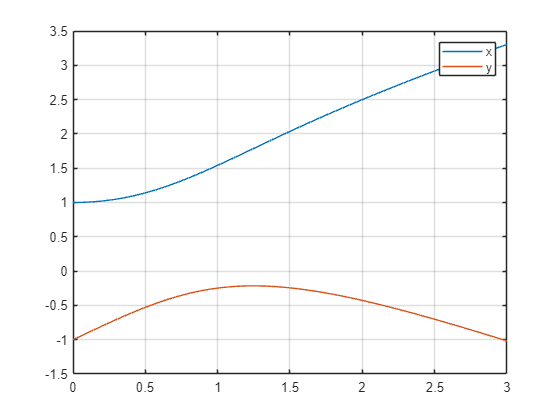

tRange = [0 3];
Y0 = [1; -1];
[tSol, YSol] = ode45(@myODEfun2, tRange, Y0);
% visualize solution
plot(tSol, YSol(:, 1))
hold on
grid on
plot(tSol, YSol(:, 2))
hold off
legend("x", "y")

# Writing an ODE Function, part 3

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves the ODE system and visualizes the solution.

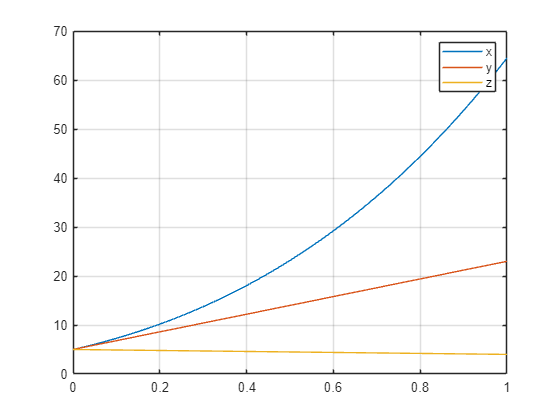

tRange = [0 1];
Y0 = [5; 5; 5];
[tSol,YSol] = ode45(@myODEfun3, tRange, Y0);
% visualize solution
plot(tSol, YSol(:, 1))
hold on
grid on
plot(tSol, YSol(:, 2))
plot(tSol, YSol(:, 3))
hold off
legend("x", "y", "z")

# Writing an ODE Function, part 4

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves the ODE system and visualizes the solution.

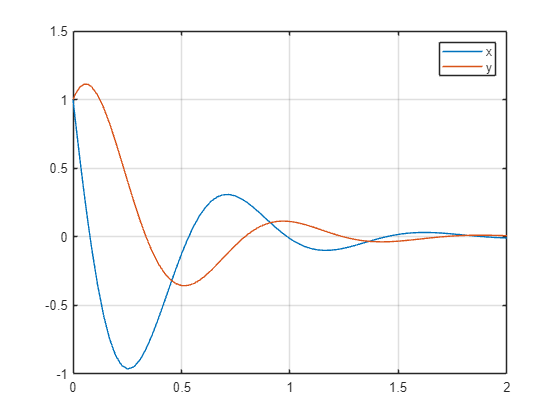

tRange = [0 2];
Y0 = [1; 1];
[tSol, YSol] = ode45(@myODEfun4, tRange, Y0);
% visualize solution
plot(tSol, YSol(:, 1))
hold on
grid on
plot(tSol, YSol(:, 2))
hold off
legend("x", "y")

## Task 1

function dYdt = myODEfun1(t, Y)
    x = Y(1);
    y = Y(2);
    
    % TODO - Complete expression for dxdt
    dxdt = x - y^2;
    
    % TODO - Complete expression for dydt
    dydt = 6;
    
    dYdt = [dxdt; dydt];
end

## Task 2

function dYdt = myODEfun2(t, Y)
    % TODO - Complete expression for x
    % x is the first element of z
    x = Y(1);
    
    % TODO - Complete expression for y
    % y is the second element of z
    y = Y(2);
    
    dxdt = sin(x + y);
    dydt = cos(x + y);
    
    dYdt = [dxdt; dydt];
end

## Task 3

function dYdt = myODEfun3(t, Y)
    x = Y(1);
    y = Y(2);
    z = Y(3);
    
    dxdt = x + 2*y + z;
    dydt = 18;
    dzdt = -1;
    
    % TODO - Complete expression for dYdt
    % dYdt is a column vector containing dxdt, dydt, and dzdt
    dYdt = [dxdt; dydt; dzdt];
end

## Task 4

function dYdt = myODEfun4(t, Y)
    % TODO - Extract x, the first element of Y
    x = Y(1);
    
    % TODO - Extract y, the second element of Y
    y = Y(2);
    
    % TODO - Complete expression for dxdt
    dxdt = -4*x - 10*y;
    
    % TODO - Complete expression for dydt
    dydt = 5*x - y;
    
    % TODO - Create dYdt, column vector containing dxdt & dydt
    dYdt = [dxdt; dydt];
end